# Week 1

CoolProp reminder

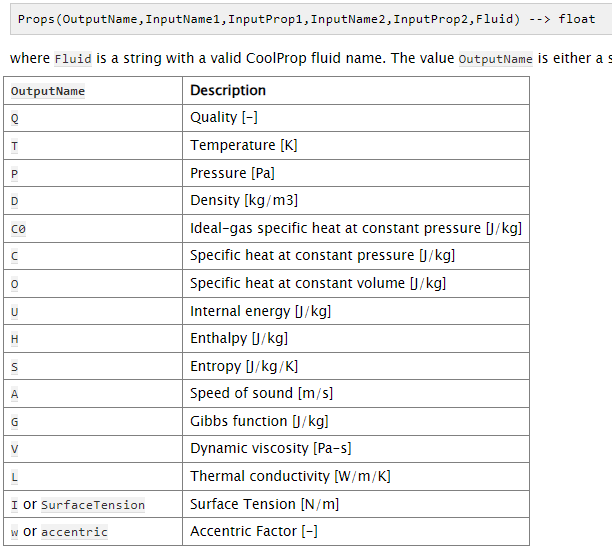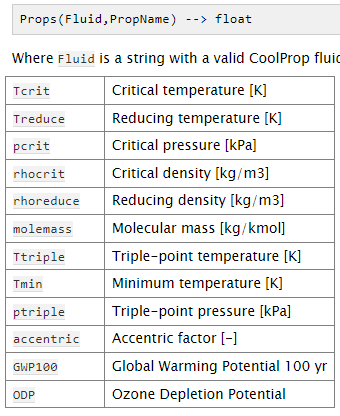

clc; clear;

CP = py.importlib.import_module("CoolProp.CoolProp")

CP =   Python module with properties:

                         FLUID_TYPE_INCOMPRESSIBLE_LIQUID: [1×1 py.int]
                                        HmassSmass_INPUTS: [1×1 py.int]
                                                   iSmass: [1×1 py.int]
                                     is_trivial_parameter: [1×1 py.builtin_function_or_method]
                                            QSmass_INPUTS: [1×1 py.int]
                                                iCp0molar: [1×1 py.int]
                                          get_debug_level: [1×1 py.builtin_function_or_method]
                                                     math: [1×1 py.module]
                                              iP_reducing: [1×1 py.int]
                                              HAProps_Aux: [1×1 py.builtin_function_or_method]
                                                HAPropsSI: [1×1 py.builtin_function_or_method]
        

Energi v. tryktab:


$$E = \Delta P \cdot \dot{V}$$


For kompressorer er det klart bedst (energimæssigt) at se tryktab efter, da volumenstrømmen der er væsentligt lavere

format default

fluid = "R134a";
mdot = 0.05;
dP_loss = linspace(0, 50e3, 100);
p1 = 2e5;
p2 = 8e5;

p1_loss = 2e5 - dP_loss; % Tryktab enten før eller efter kompressor
p2_loss = 8e5 + dP_loss; % Tryktab enten før eller efter kompressor
Q_loss = linspace(0,1000,100); % Varmetab enten før eller efter kompressor

x = 1;

eta_is = 0.7;

W_axel  = [];
W_axel2  = [];
V_slag = [];

W_axel_HL = [];
W_axel2_HL = [];

for i = 1:length(dP_loss)

    h1 = CP.PropsSI("H", "P", p1_loss(i), "Q", x, fluid)
    s1 = CP.PropsSI("S", "P", p1_loss(i), "Q", x, fluid);
    h2s = CP.PropsSI("H", "P", p2, "S", s1, fluid);

    h1_copy = CP.PropsSI("H", "P", p1, "Q", x, fluid);
    s1_copy = CP.PropsSI("S", "P", p1, "Q", x, fluid);
    h2s_copy = CP.PropsSI("H", "P", p2_loss(i), "S", s1_copy, fluid);
    h2 = (h2s - h1)/eta_is + h1;

    W_axel(end+1) = mdot*(h2s - h1)/eta_is; % watt
    W_axel2(end+1) = mdot*(h2s_copy - h1_copy)/eta_is; % watt

    % Slagvolumen
    Stempel = 50; % omdr/s
    density = CP.PropsSI("D", "P", p1_loss(i), "Q", x, fluid);
    Vdot = mdot/density;
    V_slag(end+1) = Vdot/Stempel * 1e6;
    
    

end

h1 = 3.9262e+05

h1 = 3.9258e+05

h1 = 3.9254e+05

h1 = 3.9250e+05

h1 = 3.9246e+05

h1 = 3.9242e+05

h1 = 3.9239e+05

h1 = 3.9235e+05

h1 = 3.9231e+05

h1 = 3.9227e+05

h1 = 3.9223e+05

h1 = 3.9219e+05

h1 = 3.9215e+05

h1 = 3.9211e+05

h1 = 3.9207e+05

h1 = 3.9203e+05

h1 = 3.9199e+05

h1 = 3.9195e+05

h1 = 3.9191e+05

h1 = 3.9187e+05

h1 = 3.9183e+05

h1 = 3.9179e+05

h1 = 3.9175e+05

h1 = 3.9171e+05

h1 = 3.9167e+05

h1 = 3.9163e+05

h1 = 3.9159e+05

h1 = 3.9155e+05

h1 = 3.9151e+05

h1 = 3.9146e+05

h1 = 3.9142e+05

h1 = 3.9138e+05

h1 = 3.9134e+05

h1 = 3.9130e+05

h1 = 3.9126e+05

h1 = 3.9122e+05

h1 = 3.9117e+05

h1 = 3.9113e+05

h1 = 3.9109e+05

h1 = 3.9105e+05

h1 = 3.9101e+05

h1 = 3.9096e+05

h1 = 3.9092e+05

h1 = 3.9088e+05

h1 = 3.9084e+05

h1 = 3.9079e+05

h1 = 3.9075e+05

h1 = 3.9071e+05

h1 = 3.9066e+05

h1 = 3.9062e+05

h1 = 3.9058e+05

h1 = 3.9054e+05

h1 = 3.9049e+05

h1 = 3.9045e+05

h1 = 3.9040e+05

h1 = 3.9036e+05

h1 = 3.9032e+05

h1 = 3.9027e+05

h1 = 3.9023e+05

h1 = 3.9018e+05

h1 = 3.9014e+05

h1 = 3.9010e+05

h1 = 3.9005e+05

h1 = 3.9001e+05

h1 = 3.8996e+05

h1 = 3.8992e+05

h1 = 3.8987e+05

h1 = 3.8983e+05

h1 = 3.8978e+05

h1 = 3.8974e+05

h1 = 3.8969e+05

h1 = 3.8965e+05

h1 = 3.8960e+05

h1 = 3.8955e+05

h1 = 3.8951e+05

h1 = 3.8946e+05

h1 = 3.8942e+05

h1 = 3.8937e+05

h1 = 3.8932e+05

h1 = 3.8928e+05

h1 = 3.8923e+05

h1 = 3.8918e+05

h1 = 3.8914e+05

h1 = 3.8909e+05

h1 = 3.8904e+05

h1 = 3.8900e+05

h1 = 3.8895e+05

h1 = 3.8890e+05

h1 = 3.8885e+05

h1 = 3.8881e+05

h1 = 3.8876e+05

h1 = 3.8871e+05

h1 = 3.8866e+05

h1 = 3.8861e+05

h1 = 3.8857e+05

h1 = 3.8852e+05

h1 = 3.8847e+05

h1 = 3.8842e+05

h1 = 3.8837e+05

h1 = 3.8832e+05


for i = 1:length(Q_loss)

    h1 = CP.PropsSI("H", "P", p1, "Q", x, fluid) - Q_loss(i)*mdot;
    s1 = CP.PropsSI("S", "P", p1, "Q", x, fluid);
    h2s = CP.PropsSI("H", "P", p2, "S", s1, fluid);

    h1_copy = CP.PropsSI("H", "P", p1, "Q", x, fluid);
    s1_copy = CP.PropsSI("S", "P", p1, "Q", x, fluid);
    h2s_copy = CP.PropsSI("H", "P", p2, "S", s1_copy, fluid);
    
    h2 = (h2s - h1)/eta_is + h1;
    h2_copy = (h2s - h1)/eta_is + h1_copy - Q_loss(i)*mdot;

    W_axel_HL(end+1) = mdot*(h2 - h1); % watt
    W_axel2_HL(end+1) = mdot*(h2_copy - h1_copy); % watt

end


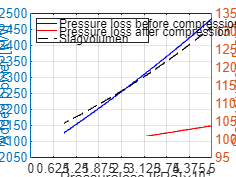


% dP plot
figure
yyaxis left
plot(dP_loss, W_axel,"DisplayName","Pressure loss before compression","Color","blue","LineStyle","-")
hold on
plot(dP_loss, W_axel2,"DisplayName","Pressure loss after compression","Color","red","LineStyle","-")
hold off
ylabel("Added power [kW]")

yyaxis right 
plot(dP_loss, V_slag, "DisplayName","Slagvolumen","Color","black","LineStyle","--")
ylabel("Slagvolumen [ccm]")

grid()
xticks(linspace(0,50e3,9))
xlabel("Pressureloss [kPa]")
legend("location","northwest")

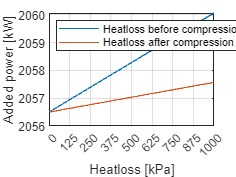


% Q_loss plot
figure
plot(Q_loss, W_axel_HL,"DisplayName","Heatloss before compression")
hold on
plot(Q_loss, W_axel2_HL,"DisplayName","Heatloss after compression")
hold off
xticks(linspace(0,1000,9))
grid()
xlabel("Heatloss [kPa]")
ylabel("Added power [kW]")
legend("location","northwest")

format bank
% water
kelvin = 273.15;
density = 1000;
cp = 4180;
fluid = "water";
U = 500;

% HX
nPlates = 10;
A = 0.07*0.2 * nPlates;

% Bruser
tcIn_b = 10;
mdot_b = 10/60; % kg/s

% Fjernvarme
tcIn_fj = 60;
mdot_fv = 350/3600; % kg/s

syms tcOut_b tcOut_fj

LMTD = ((tcIn_fj- tcOut_b) - (tcOut_fj-tcIn_b))/(log(((tcIn_fj- tcOut_b))/(tcOut_fj-tcIn_b)));
Q_lmtd = U*A*LMTD;

Q_b = mdot_b * cp * (tcOut_b - tcIn_b) == Q_lmtd;
Q_fj = mdot_fv * cp * (tcIn_fj - tcOut_fj) == Q_lmtd;


eqs = [Q_b; Q_fj];

sols = vpasolve(eqs, symvar(eqs))

sols = struct with fields:
     tcOut_b: 14.419383403155244444327525523356
    tcOut_fj: 52.423914166019580952581384817104




% MED VIRKNINGSGRAD I STEDET
syms tcOut_b tcOut_fj
Q_ideal = mdot_fv * cp * (tcIn_fj - tcIn_b);
eta = 0.6;
Q_act = Q_ideal * eta;

t_Q_b = mdot_b * cp * (tcOut_b - tcIn_b) == Q_act;
t_Q_fj = mdot_fv * cp * (tcIn_fj - tcOut_fj) == Q_act;

eqs = [t_Q_b; t_Q_fj];

sols_eta = vpasolve(eqs, symvar(eqs))

sols_eta = struct with fields:
     tcOut_b: 27.5
    tcOut_fj: 30.0
